## Forward Tutorial

Get the general settings (data path, source code path, generated report path)

run("CIRLSetup.m")

HR settings of a 200x200x200 Bead for the 3-slit Tunable system

[ psfpar, psfpari ] = PSFConfigNoAber();
X     = 200;                        % discrete lateral size in voxels
Y     = 200;                        % discrete lateral size in voxels
Z     = 200;                        % discrete axial size in voxels
dXY   = 0.025;                      % lateral voxel scaling in microns ---- for 20X lens (6.4/20)....for 60X lens (6.4/63)
dZ    = 0.025;                      % axial voxel scaling in microns
uc    = 2*psfpar.NA/psfpari.v(1);   % cycle/um
offs  = [0, 0, 0];                  % offset from the standard values of phi
phi   = [0, 1, 2]*(2*180)/3;        % lateral phase
theta = [0, 60, 120];               % orientation
um    = [0.8, 0.8, 0.8]*uc;         % lateral modulating frequency
x0    = 0.326;  % in mm
fL1   = 100;    % in mm
fL2   = 250;    % in mm
fMO   = 160/63;
wm    = ((x0*fL2)/(2*fL1*fMO))*um;  % axial modulating frequency
phizDeg   = 46.0;                   % axial phase
Nslits    = 3;

s = struct('X', X, 'Y', Y, 'Z', Z, 'dXY', dXY, 'dZ', dZ, 'phi', phi,'theta', theta,'um', um,'x0',x0, 'fL1', fL1, 'fL2', fL2, 'fMO', fMO, 'wm', wm, 'phizDeg', phizDeg, 'Nslits', Nslits)

s = struct with fields:
          X: 200
          Y: 200
          Z: 200
        dXY: 0.0250
         dZ: 0.0250
        phi: [0 120 240]
      theta: [0 60 120]
         um: [4.3495 4.3495 4.3495]
         x0: 0.3260
        fL1: 100
        fL2: 250
        fMO: 2.5397
         wm: [0.6979 0.6979 0.6979]
    phizDeg: 46
     Nslits: 3


Settings = DataFrame.fromStruct(s);
disp(Settings)

     X      Y      Z      dXY      dZ            phi               theta                     um                 x0      fL1    fL2     fMO                   wm                  phizDeg    Nslits
    ___    ___    ___    _____    _____    _______________    _______________    __________________________    _____    ___    ___    ______    _____________________________    _______    ______

    200    200    200    0.025    0.025    0    120    240    0     60    120    4.3495    4.3495  

Settings.uc = 2*psfpar.NA/psfpari.v(1);
Settings.offs = offs

Settings =      X      Y      Z      dXY      dZ            phi               theta                     um                 x0      fL1    fL2     fMO                   wm                  phizDeg    Nslits      uc         offs    
    ___    ___    ___    _____    _____    _______________    _______________    __________________________    _____    ___    ___    ______    _____________________________    _______    ______    ______    

HR point spread function

h  = PSFAgard(Settings);

XY = 200

Z = 200

dXY = 0.0250

dZ = 0.0250

HR modulating pattern

[im, jm, ~] = PatternTunable3DNSlits(Settings);

HR bead object construction

Radius    = 2/2;
Thickness = 1/2;
ob        = SphericalShell(Settings, Radius, Thickness);

Analysis of HR bead object

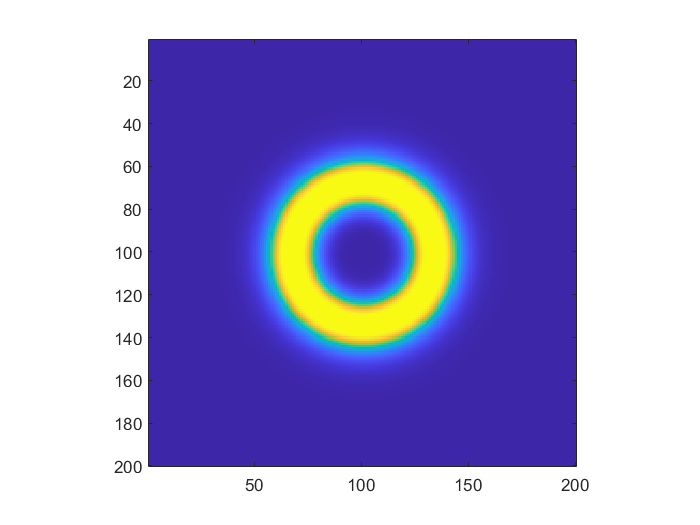

figure; imagesc(ob(:,:,1+Z/2)); axis square;

HR forward images

g  = ForwardModel(ob, h, im, jm);

Analysis of HR forward images

[Y, X, Z, Nthe, Nphi] = size(g)

Y = 200

X = 200

Z = 200

Nthe = 3

Nphi = 3

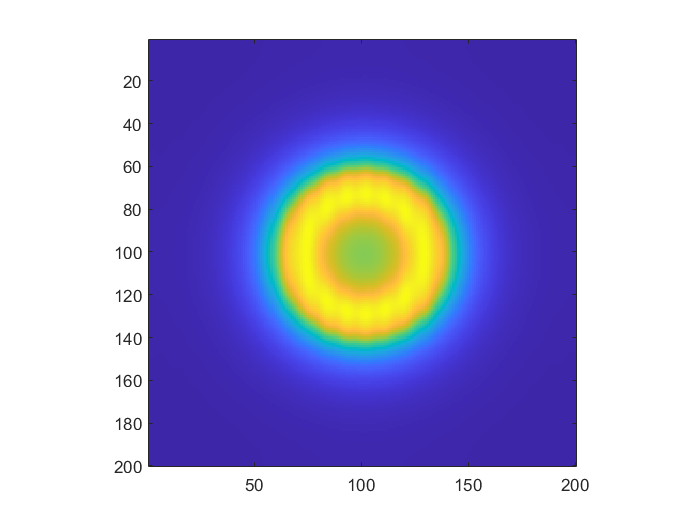

curTheInd = 1;  % theta index that one is interested in
curPhiInd = 1;  % phi   index that one is interested in
figure; imagesc(g(:,:,1+Z/2,curTheInd,curPhiInd)); axis square;

Discussion questions:

- Difference between the forward images of different phases and orientations? (in real and frequency domains)

- Difference between the forward images and the original one?

- How does one quantify the different? Which metrics will be suitable?

- How does one get the low-resolution of the forward image? How does one compare the LR image with the HR image?